## Method

We aimed to answer this question by constructing an energy balance model that tracks the internal energy of the Earth as a single, average value for the sake of time. 

Our first 3 iterations were meant to familiarize us with the physics at hand and were aimed at introducing all of the necessary parameters and equations for incoming and outgoing energy, as well as calculating an equilibrium temperature. 

Those parameters that are used in our model are:

- S - Energy Flux Density (Energy flowing through 1 $m^2$, $W/m^2$)

- $\sigma
$ - Stefan-Boltzmann Constant (Used to calculate black-body radiation)

- $\epsilon$ - Greenhouse factor (Portion of outgoing energy that is able to escape the atmosphere and is not trapped by greenhouse gases)

- $\alpha$ - Albedo (Reflectivity - portion of incoming energy that is reflected back out and not absorbed)

Their initial values in our model are as follows

- S = 1367.6 (constant)

- $\sigma
$ = $5\ldotp 67*{10}^{-8}$

- $\epsilon = 
$ .6011 (given by findGreenhouseEffect; calculated to be the equilibrium greenhouse effect at 288K)

- $\alpha =$ .3142 (given by findAlbedo; calculations given in following section)

### Finding the Albedo

The method we are using to calculate the albedo is to first calculate the global percentage of ice coverage, and then converting that to albedo. Because the earth has so much variation, there isn't an exact formula we can plug into to return the values we need, so we have had to turn to empirical approimations of natural phenomena. Nonetheless, they replicate natural behavior well enough for the purposes of our model.

We calculate the ice coverage by first calculating the at any given point at which latitude the Earth's temperature reaches -2 degrees Celsius (this is when enough sea ice forms for scientists to classify the area as covered in ice). Given an average temperature, our equation for the temperature at each latitude is:


$$Temperature = 27-43(sin^2(\pi*L/180)) + \mu T - 288 $$


where $L$ is the latitude and $\mu T$ is the average global temperature that our model is tracking. By solving this equation for L when Temperature = -2, we can find the extent (what we refer to as the ice point) of the ice coverage represented as a latitude between 0 and 90.

The final step is to take this number and calculate the percentage of the Earth that it represents. Although it might seem this way initially, we cannot simply divide our ice point by 90. The Earth is a sphere, so every latitude represents a different amount of the Earth's surface. The following is our equation for taking that ice point and converting it into a fraction.


$$Ice  Coverage  = \frac {\int_{p}^{90}cos(\frac {p*pi}{180})}{\int_{0}^{90}cos(\frac {p*pi}{180})}$$


Lastly, we must convert this ice coverage into an albedo number that we can then use in our model. Knowing that the real world albedo at our temperature of 288K is about .31 and that the albedo of our planet if it was covered in ice would be roughly .84, we developed a linear equation to relate the two, as seen below.


$$\alpha = 0.00638554216867 * iceCoverage + .2$$


These calculations are contained in the findIceCoverage and findAlbedo functions respectively.

### Finding Equilibrium Points

With all of our parameters sorted, the next script we wrote endeavors to prove that there are multiple points in which the energy in and the energy out are in equilibrium - specifically a very cold equilibrium that suggests the possibility for a snowball Earth scenario. 

The findEquilibriums function sweeps the temperature from 150K to 300K and calculates and plots the incoming energy and the outgoing energy as two separate lines. Their intersection defines an equilibrium point.

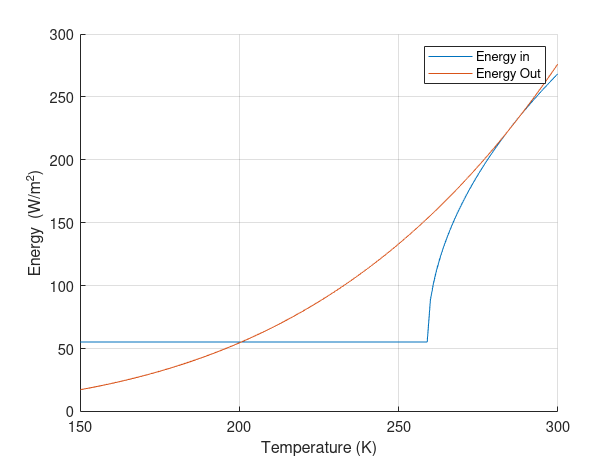

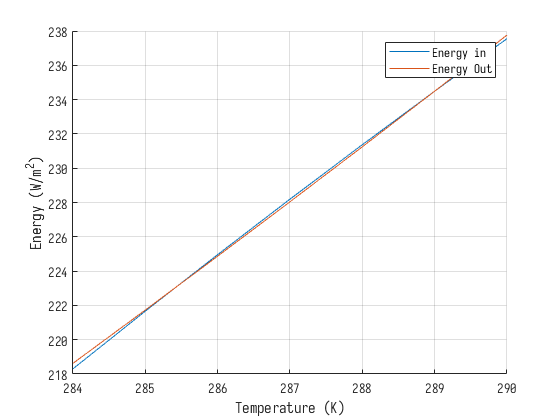

findEquilibriums

The first graph shows our entire temperature sweep, including one very clear equilibrium point very close to 200K. Because the top section of the grpah where the lines approach each other is difficult to see clearly, a zoomed in version is also included where the energy in rises slightly above energy out for a few degrees and then dips back below it. The intersection at 288K is an equilibrium point. The smaller one, however, at roughly 285K, is somewhat of a false equilibrium - it is an unstable equilibrium that the Earth would never reach. This is because of the way the energy is changing - if the temperature drops even just shy of that point, the energy out becomes larger than the energy in and the planet begins to cool at an exponential rate, and the opposite is true for the other side. 